Demonstration of the extraction of an energy motion signal from a webcam video.

videoPath = 'E:\Data Jeremie\Bilateral Stim and Resting State dataset\M4\M4_rs_10min\M4_rs_monitoring.avi';
syncFilePath = 'E:\Data Jeremie\Bilateral Stim and Resting State dataset\M4\M4_rs_10min\M4_rs_monitoring.mat';
monitoringVideo = webcamMovie(videoPath,syncFilePath);
whiskerMask = monitoringVideo.createMask;

rawWhiskerSignal = monitoringVideo.extractROIsignal(whiskerMask);

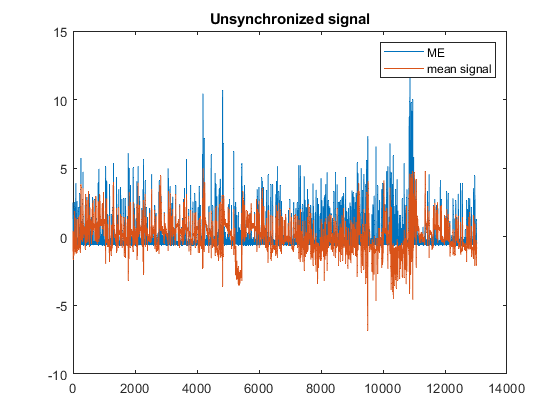

whiskerSignal = (rawWhiskerSignal-mean(rawWhiskerSignal))/std(rawWhiskerSignal);
syncWhiskerSignal = monitoringVideo.synchronizeSignal(whiskerSignal);
whiskerME = abs(diff(whiskerSignal));
whiskerME = (whiskerME-mean(whiskerME))/std(whiskerME);
syncWhiskerME = abs(diff(syncWhiskerSignal));
syncWhiskerME = (syncWhiskerME-mean(syncWhiskerME))/std(syncWhiskerME);
figure;
plot(whiskerME);
hold on
plot(whiskerSignal);
legend('ME','mean signal');
title('Unsynchronized signal');

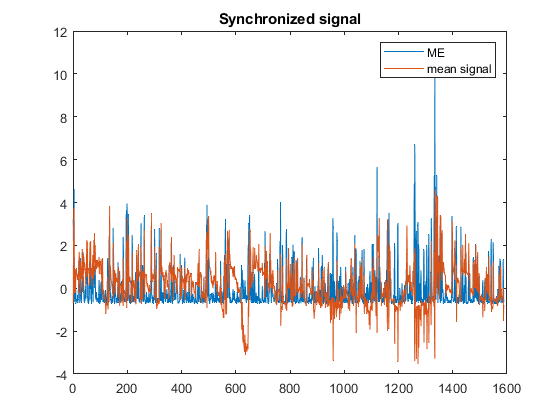


figure;
plot(syncWhiskerME);
title('Synchronized signal');
hold on
plot(syncWhiskerSignal);
legend('ME','mean signal');